##  Задание 2. Область устойчивости 

Параметры для запуска симуляции

simTimeStart = 0;
simTimeEnd = 100;
step = 0.02;
g = 1;
modelName = 'task2'; 

Эксперимент 1-й

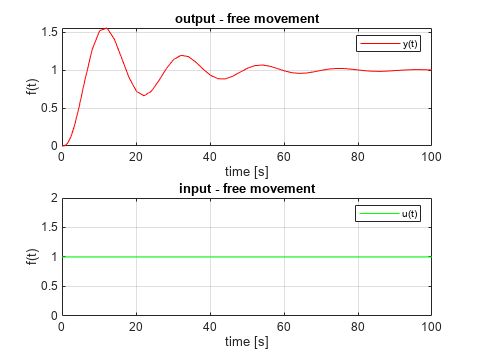

K = 1/2; T1 = 1; T2 =5;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
g = 1 * ones(1, length(time))';

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)');

subplot(2,1,2);
plot(time, g, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task2_exp1')

Эксперимент 2-й

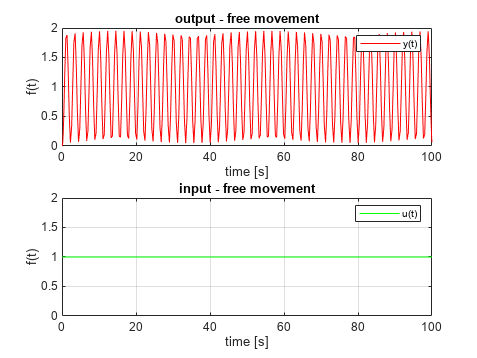

K = 9; T1 = 1; T2 =1/8; g = 1;
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
g = 1 * ones(1, length(time))';

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)');
subplot(2,1,2);
plot(time, g, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task2_exp2')

Эксперимент 3-й

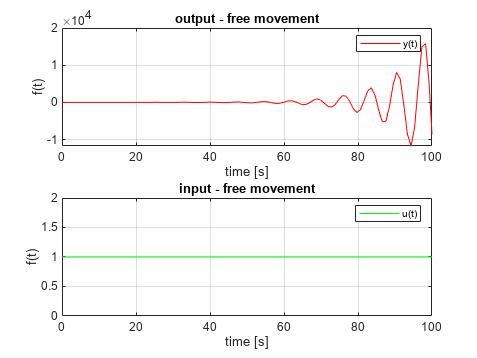

K = 4; T1 = 4; T2 = 2/3; g = 1;

load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.simout.Time;                
y_out = out.simout.Data; 
g = 1 * ones(1, length(time))';

figure;
subplot(2,1,1);
plot(time, y_out, 'r');
title('output - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('y(t)');

subplot(2,1,2);
plot(time, g, 'g'); 
title('input - free movement');   
xlabel('time [s]');                  
ylabel('f(t)');                      
grid on;
legend('u(t)');
save_file('output_task2_exp3')

**Функция, чтобы сохранить файл в папку**

function save_file(name)
    path = 'D:\Math\LinearSystemsOfAutoControl\linear_systems_labs\lab2\latex2\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end